t = -2*pi:0.1:2*pi;
A=256;
y_continua = A*sin(t);
% Graficamos la señal continua
figure;
disp 'señal continua figure 1'

señal continua figure 1


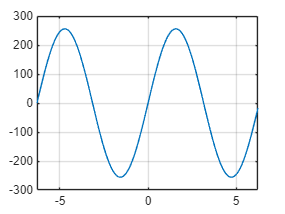

plot(t, y_continua);
grid on;

frecuencia = 1; 
cantidad_muestras = 7;
tiempo_discreto = 0:1:2*cantidad_muestras-1;
figure;
disp 'señal discreta figure 2'

señal discreta figure 2


senal_seno_discreta = A*sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras)

senal_seno_discreta =          0  200.1489  249.5815  111.0742 -111.0742 -249.5815 -200.1489   -0.0000  200.1489  249.5815  111.0742 -111.0742 -249.5815 -200.1489


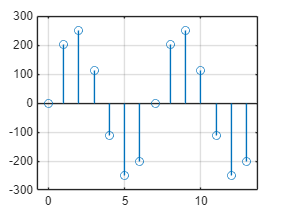

stem(tiempo_discreto, senal_seno_discreta);
grid on;

figure;
disp 'señal discreta cuantizada figure 3'

señal discreta cuantizada figure 3


senal_seno_discreta_Q = int8(A * sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras))

senal_seno_discreta_Q = 1×14 int8 row vector
      0    127    127    111   -111   -128   -128      0    127    127    111   -111   -128   -128


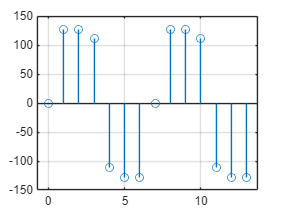

stem(tiempo_discreto, senal_seno_discreta_Q);
grid on;

figure
frecuencia = 1; 
tiempo_discreto = 0:1:2*cantidad_muestras-1; 
disp('señal discreta figure 4')

señal discreta figure 4


senal_seno_discreta_Q1 = round(A * sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras),1)

senal_seno_discreta_Q1 =          0  200.1000  249.6000  111.1000 -111.1000 -249.6000 -200.1000         0  200.1000  249.6000  111.1000 -111.1000 -249.6000 -200.1000


stem(tiempo_discreto, senal_seno_discreta_Q1);
grid on;

disp 'Espacio disponible para diseñar un algoritmo que permita calcular y graficar el error de cuantización para las figuras 2, 3 y 4 en comparación con la figura 2.'

Espacio disponible para diseñar un algoritmo que permita calcular y graficar el error de cuantización para las figuras 2, 3 y 4 en comparación con la figura 2.
